# Exercise 1

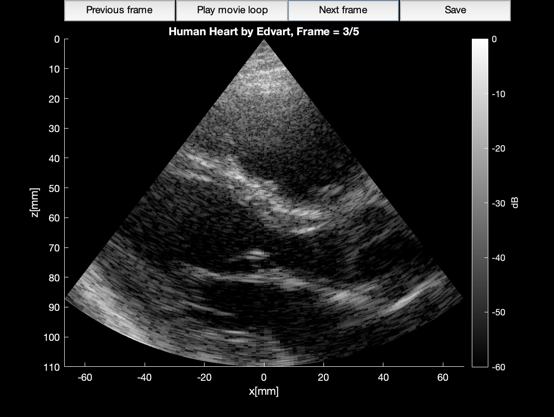

# Exercise 2

## Task 1

#### a)

$x_{row}$ creates a row vector with values from 0 to 6, with 2 as the increment between elements.

$x_{col}$ returns the transpose of $x_{row}$, giving a column vector.

$x_1$ is a row vector (rows separated by commas) with elements ${1, 2, 3}$

$x_2$ is a column vector (columns separated by semicolons) with the same elements

$x_3$ creates a row vector with 4 elements, with values interpolated from 1 to 10

#### b)

For this task, I will use $\vec{x}$ and ${\vec{x}}^T$to represent `x_col and x_row:`

$a = {\vec{x}}^T {\vec{x}} = \vec{x}\cdot \vec{x}$. This a dot product, returning a scalar.

$B = \vec{x}{\vec{x}}^T$ Produces an nxn matrix, for $\vec{x} \in \mathbb{R}^n$ (outer product).

$C = \vec{x}^T .* \vec{x}$ Uses the element-wise multiplication operator on a row vector and a column vector. In this case, it is as though $\vec{x}$ is treated as a single element. So we get a matrix $C$, where each column $C_i$ is equal to ${\vec{x}}^T_i*\vec{x}$

$\vec{d} = {\vec{x}}^T .* {\vec{x}}^T$ Uses element-wise multiplication on the row vector and the transposed column vector (x_col'), which equal to the row vector itself. So, $\vec{d}$ is a row vector containing the squared elements of $\vec{x}$.

$\vec{e} = {({\vec{x}^T)}^T .* \vec{x} = \vec{x} .* \vec{x}$. This is effectively an element-wise multiplication of $\vec{x}$ with itself. $\vec{e}$ is then a column vector containing the squared elements of $\vec{x}$, i.e $\vec{d} = \vec{e}^T$d

#### c)


$$\vec{z} = \vec{x} + 2j*\vec{x}$$



$$\vec{z} = [0, 2, 4, 6] + 2j*[0, 2, 4, 6]$$



$$\vec{z} = [0, 2, 4, 6] + [0, 4j, 8j, 12j]$$



$$\vec{z} = [0+0j, 2+4j, 4+8j, 6+12j]$$


#### d)

The ctranspose operator applies the complex conjugate transpose, so all complex numbers have their imaginary parts negated, in addition to applying the standard transpose.

## Task 2

#### a)

matrix_3x3 = [[1;2;3], [4;5;6], [7;8;9]]

matrix_3x3 =      1     4     7
     2     5     8
     3     6     9


matrix_5x5 = [ones([1 5])', zeros([5 4])]

matrix_5x5 =      1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0


#### b)

The multidimensional $B$ looks like a cube, with a depth of 2, or like a 2D image with resolution 6x3, and 2 color channels.

We could plot B as an image with two channels, or as a cube in 3D space. Adding more dimensions to the data makes visualization harder, as we need to add more degrees of freedom to the plot. It might be necessary to make multiple plots at different spaces (like contours).

#### c)

sum1 = sum(B) takes each column of B and returns the sum of its elements, flattening the cube.

sum2 = sum(B, 2) does the same thing, except the summation now happens row-wise.

sum3 = sum(B, 3) sums along the depth-axis, so the result is a 2D array with no depth.

sum4 = sum(B, 'all') returns the sum of all elements of B, $\sum_{i,j,k}^{} B_{ijk}$

sum5 = sum(sum(sum(B))) effectively sums and flattens the cube 3 times, returning a 1x1x1 array (scalar) which is the sum of all elements.

#### d)

A singleton dimension is like a redundant dimension which only has a single element.

For example, [[1]] has two singleton dimensions, as we are using a 2D object to represent a single number.

The squeeze function takes our sum1 object, which is like a cube (3D) with height 1, and returns a lower-dimensional array (2D) by removing the singleton dimension.

#### Optional:

Kind of close.